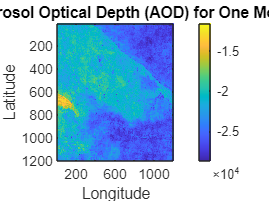

% Import necessary packages
import matlab.io.hdf4.*
import matlab.io.hdfeos.*

% Specify the directory containing your HDF-EOS files
directory = 'F:/Internship IITM/Jan/';

% Get a list of all HDF-EOS files in the directory
file_list = dir(fullfile(directory, '*.hdf'));

% Initialize a cell array to store AOD data from each file
num_files = length(file_list);
aod_data_cell = cell(1, num_files);

% Loop through each HDF-EOS file
for i = 1:num_files
    % Open the HDF-EOS file in read-only mode
    file_name = file_list(i).name;
    file_id = gd.open(fullfile(directory, file_name), 'rdonly');

    % Attach to the grid object
    GRID_NAME = 'grid1km';
    grid_id = gd.attach(file_id, GRID_NAME);

    % Read data from a data field
    DATAFIELD_NAME = 'Optical_Depth_055';
    [data, lat, lon] = gd.readField(grid_id, DATAFIELD_NAME, [], [], []);

    % Convert the data to double type for plotting
    data = double(data);

    % Detach from the Grid Object
    gd.detach(grid_id);

    % Close the file
    gd.close(file_id);

    % Squeeze the data to remove singleton dimensions
    data = squeeze(data(:,:,1));

    % Store the AOD data in the cell array
    aod_data_cell{i} = data;
end

% Concatenate AOD data from all files along the third dimension
aod_data = cat(3, aod_data_cell{:});

% Perform further processing or analysis on the concatenated AOD data
% For example, you can compute the mean along the time dimension
mean_aod_data = mean(aod_data, 3);

% Visualize the mean AOD data
figure;
imagesc(mean_aod_data);
colorbar;
title('Mean Aerosol Optical Depth (AOD) for One Month');
xlabel('Longitude');
ylabel('Latitude');